clearvars;

% Init param
M = 4;
[x, q]= PAM_generator(M); % for equiprobable symbols

N = 2;
w = [sqrt(pi)/2, sqrt(pi)/2];
z = [-1/sqrt(2), 1/sqrt(2)];
SNR = 1.0;

rho = 0;
max_rho = 1;
delta = 0.001;
E0_values = [];  % Pel display
rho_values = []; % Pel display

maxE0 = -Inf;
best_rho = -1;

% E0 computation wiht matrices
 % Time start -----------------------------------------------
tic;
[Q, pi_, G] = matrix_generator(N, q, x, w, z, SNR);

while rho <= max_rho
    E0_i = E0_matrix(Q, pi_, G, rho);
    E0_values = [E0_values, E0_i];      % Pel display
    rho_values = [rho_values, rho];     % Pel display                
    if E0_i > maxE0
        maxE0 = E0_i;
        best_rho = rho;
    end
    rho = rho + delta;
end

elapsed_time = toc; % ------------------------------------------
disp(['Temps execució: ', num2str(elapsed_time), ' segons']);

Temps execució: 0.040197 segons


% Display
disp("Rho for which E0 is max:");

Rho for which E0 is max:


disp(best_rho);

    0.9990



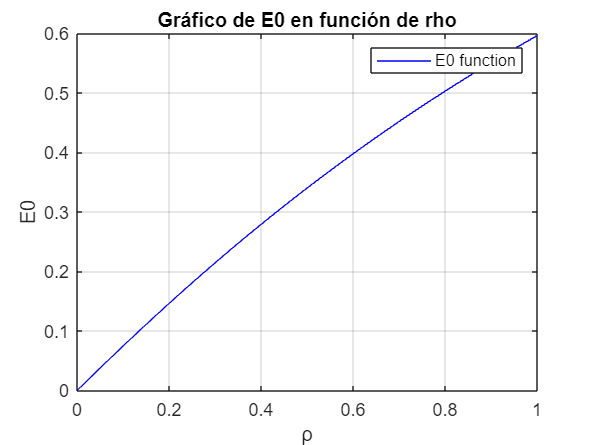


% Gràfica d'E0 respecte rho
plot(rho_values, E0_values, 'b', 'DisplayName', 'E0 function');
xlabel('ρ');
ylabel('E0');
title('Gráfico de E0 en función de rho');
legend;
grid on;

% Per E0(1)
%[Q, pi_, G] = matrix_generator(N, q, x, w, z, SNR);
tic;
E = E0_matrix(Q, pi_, G, 1);
elapsed_time = toc; % ------------------------------------------
disp(['Temps execució: ', num2str(elapsed_time), ' segons']);

Temps execució: 0.0030713 segons


disp(E)

    0.5961

